# ME 419 Hydraulic Lab 

**Names:** Julia Fay, Aiden Taylor 

**Date:** 2024.3.7

**Class:** ME419

**Description: **The purpose of this file is to simulate the hydraulic controller using a simulink model to compare to experimental results. 

## System Properties 

%Physical Properties 
Wm = 23; %lbs 

Wextra = 6; %lbs 

Wtot = Wm+Wextra; %lbf

m_ft = Wtot/32.174; %slugs (lbf*s^s/ft)

m = m_ft/12; %lbf*s^2/in mass of system. make sure units are in inches 

A = pi()*((0.5/2)^2-(0.25/2)^2);  %area of the piston surface 

%Gain Values 

Kp = 28;  %controller proportional gain 

Ka = 4.6; %amplifier gain. The input to the servo amp from the computer has a full-scale range of
          %±10 V. The output from the servo amp is in the range of ±50 mA.

Kq = 0.0125; %servo valve gain. controls flow of oil into the cylinder 

b = 0; %friction coefficient 

Kpot = 0.588; %potentiometer gain 

Kcmp = 1/0.588; %computer calculation gain because Kpot*Kcmp = 1

Kd = 0;

Ki = 0;

%Calculated Values

beta_Vt = 13305; %4*bulk modulus of the fluid/total volume of the fluid between the valve and piston 

Kce = 0.001; %reduction in flow due to backpressure 


## Block Diagram 

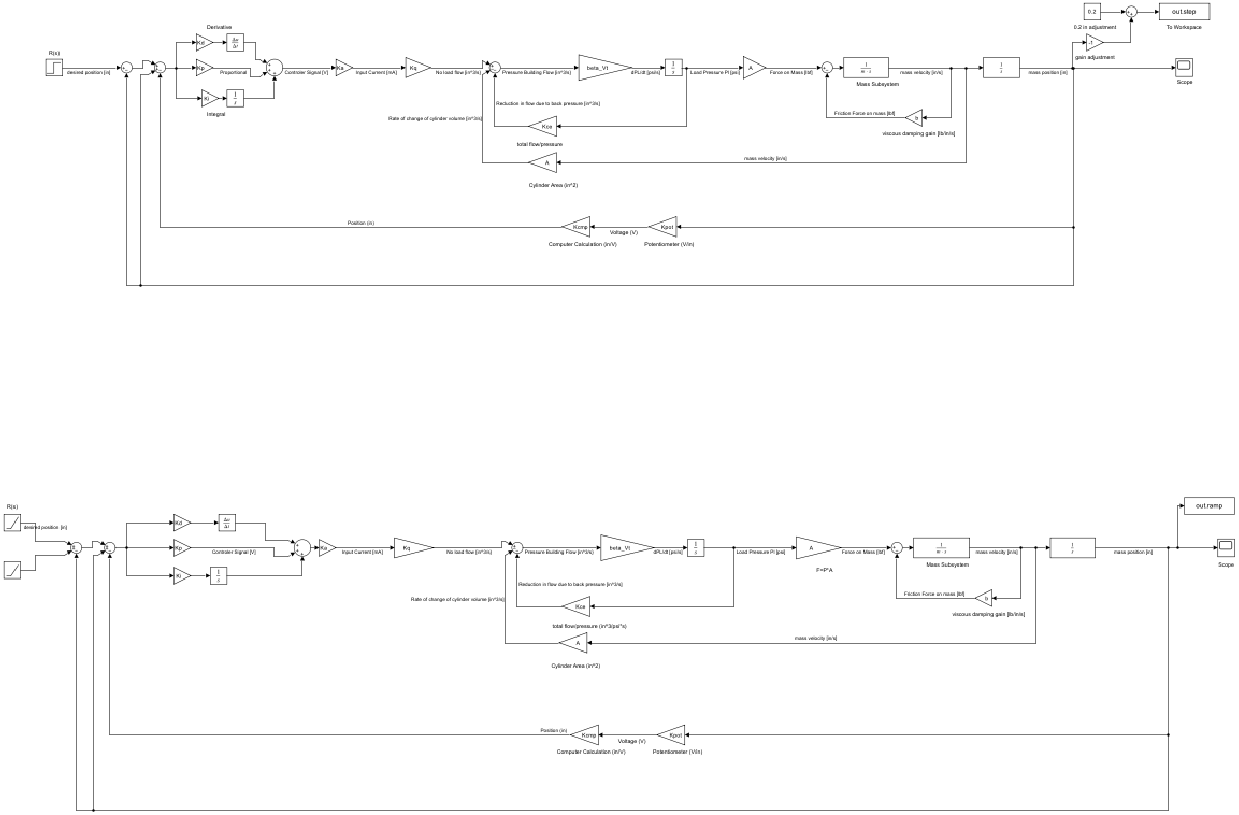

snapshotModel('Hydraulic_Lab_BD') %output simulink image

## Week 1 

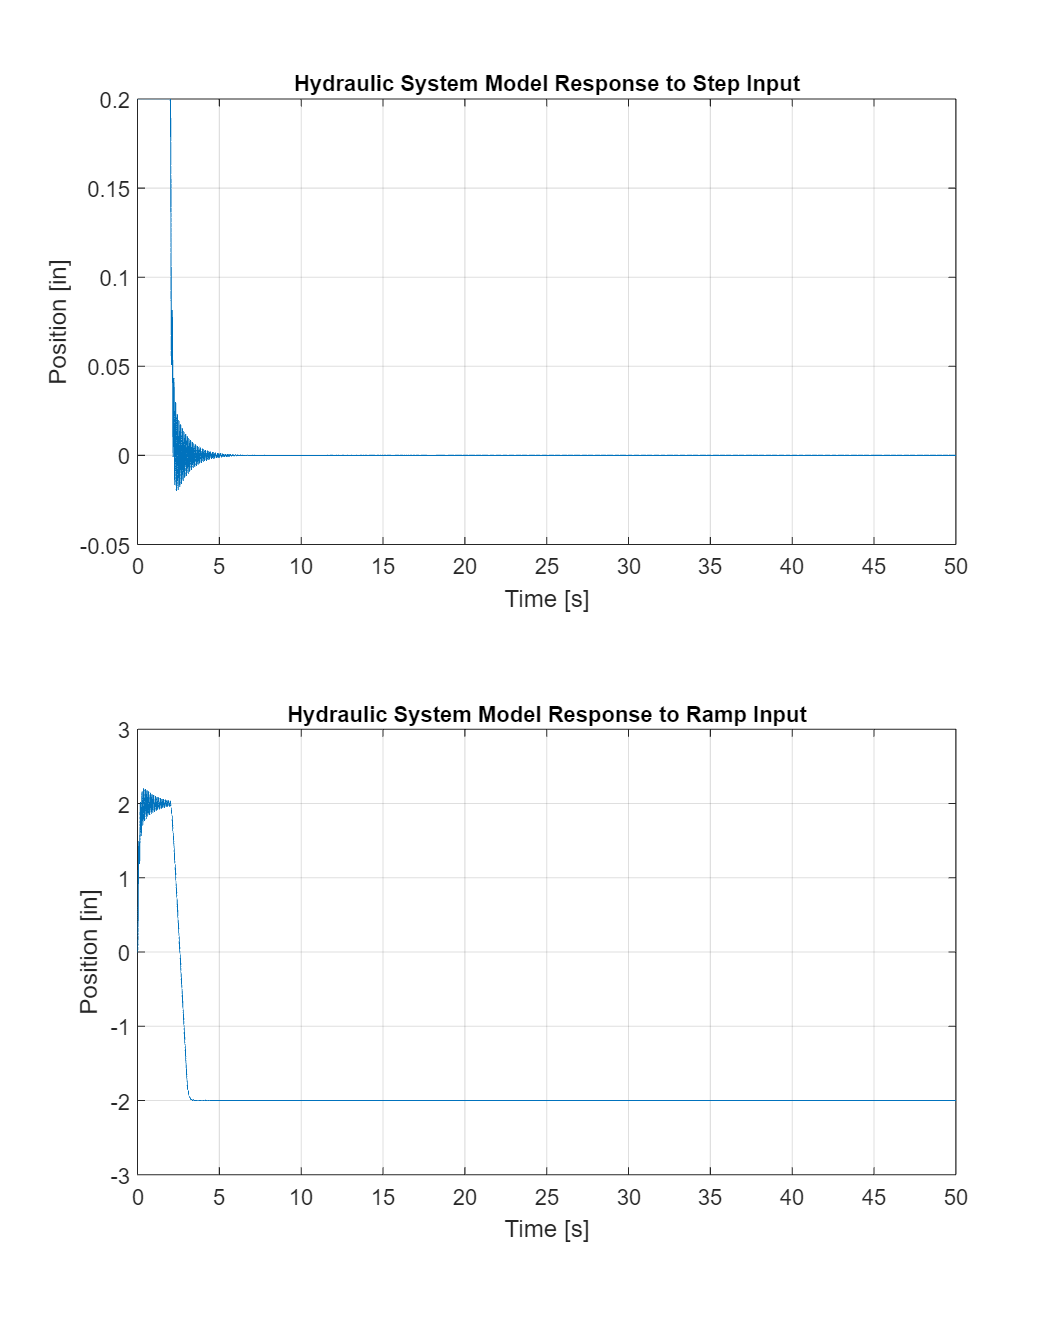

%run simulation 
run1 = sim('Hydraulic_Lab_BD.slx');

%create a tiled layout 
fig1 = figure();
tl = tiledlayout(2,1);         
fig1.Position(3:4) = [560*3 420*5]; %scale subplot

%plot the results for case 1 and format
nexttile; 
plot(run1.tout,run1.step)
xlabel("Time [s]");
ylabel("Position [in]");
%axis([0 10 -0.1 0.6]);
title('Hydraulic System Model Response to Step Input','FontSize',10,'FontWeight','bold');
grid on

%plot the results for case 2 and format
nexttile; 
plot(run1.tout,run1.ramp)
xlabel("Time [s]");
ylabel("Position [in]");
%axis([0 10 -1 9]);
title('Hydraulic System Model Response to Ramp Input','FontSize',10,'FontWeight','bold');
grid on

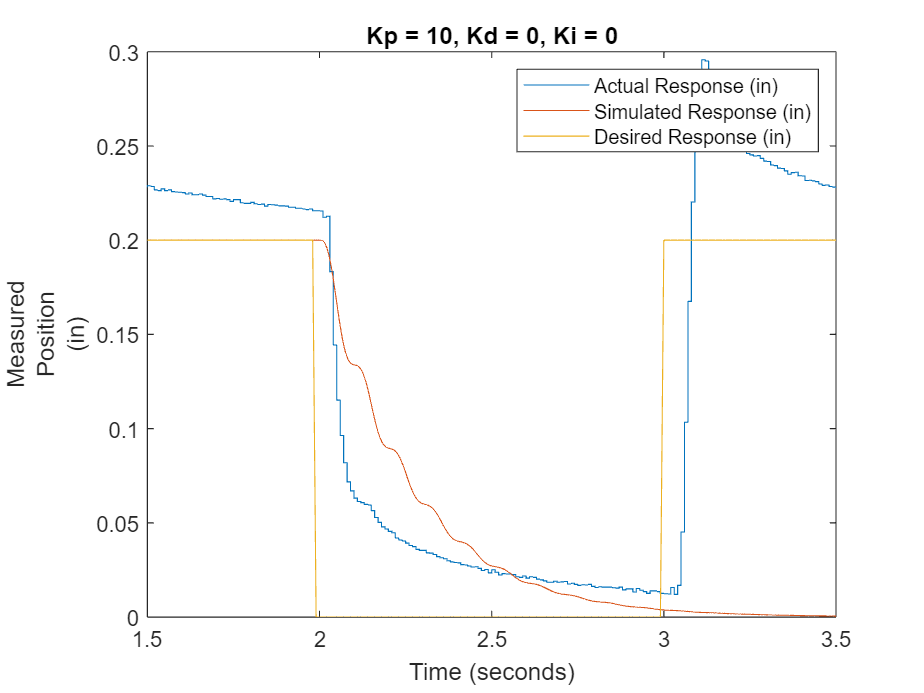

%week 1 part 4a 
Kp = 10;
Kd = 0;
Ki = 0;
run4a = sim('Hydraulic_Lab_BD.slx');
data4a = load('4a-R12-3.mat');
data4a = data4a.data(1);
response = data4a{4}.Values;
fig4a = figure(); 
plot(response)
hold on
plot(run4a.tout, run4a.step)
hold on 
plot(data4a{2}.Values)
hold on 
xlim([1.5 3.5])
legend('Actual Response (in)', 'Simulated Response (in)', 'Desired Response (in)')
title('Kp = 10, Kd = 0, Ki = 0')
hold off

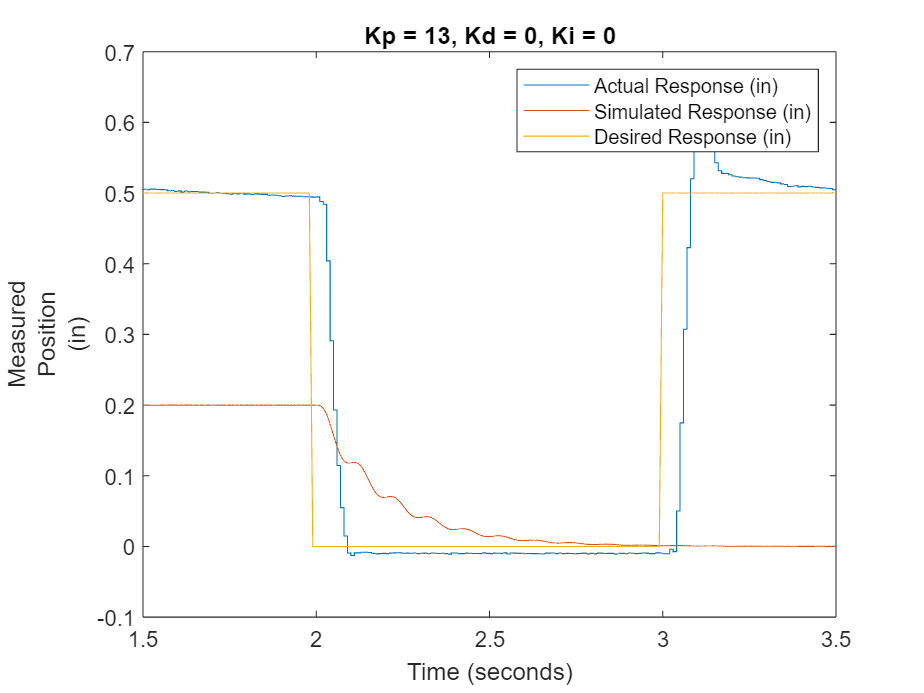

%week 1 part 4b
Kp = 13;
Kd = 0;
Ki = 0;
run4b = sim('Hydraulic_Lab_BD.slx');
data4b = load('4b-R12-3.mat');
data4b = data4b.data(1);
response = data4b{4}.Values;
fig4b = figure(); 
plot(response)
hold on
plot(run4b.tout, run4b.step)
hold on 
plot(data4b{2}.Values)
hold on 
xlim([1.5 3.5])
legend('Actual Response (in)', 'Simulated Response (in)', 'Desired Response (in)')
title('Kp = 13, Kd = 0, Ki = 0')
hold off

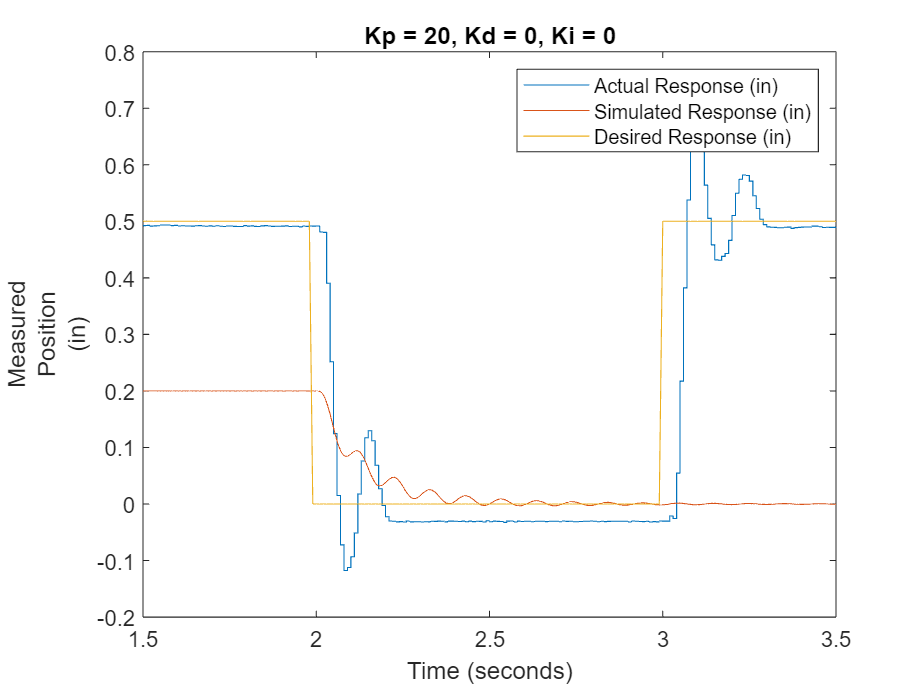


%week 1 part 4c 
Kp = 20;
Kd = 0;
Ki = 0;
run4c = sim('Hydraulic_Lab_BD.slx');
data4c = load('4c-R12-3.mat');
data4c = data4c.data(1);
response = data4c{4}.Values;
fig4c = figure(); 
plot(response)
hold on
plot(run4c.tout, run4c.step)
hold on 
plot(data4c{2}.Values)
hold on 
xlim([1.5 3.5])
legend('Actual Response (in)', 'Simulated Response (in)', 'Desired Response (in)')
title('Kp = 20, Kd = 0, Ki = 0')
hold off

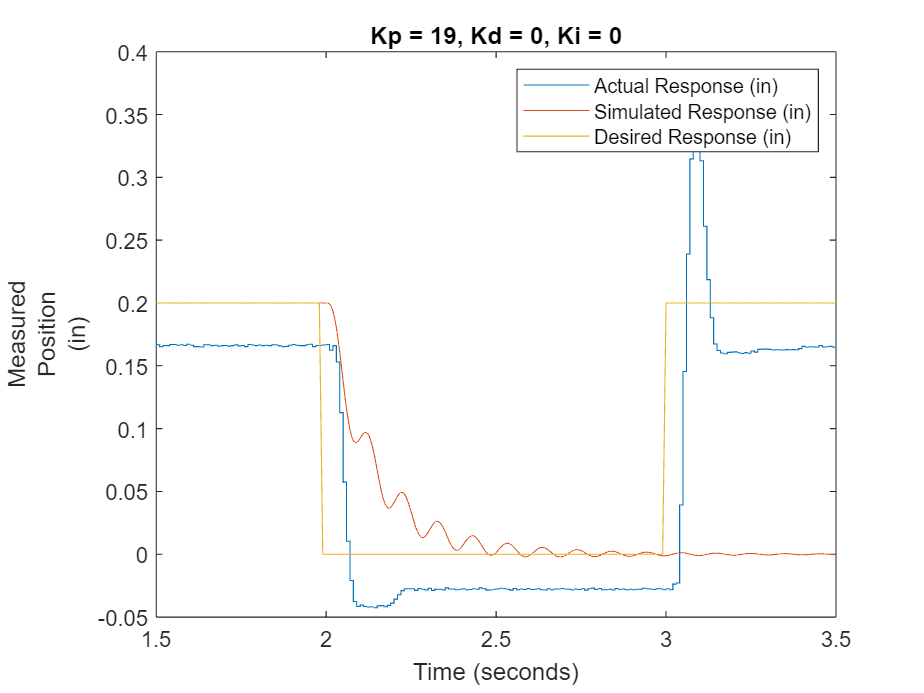


%week 1 part 4d 
Kp = 19;
Kd = 0;
Ki = 0;
run4d = sim('Hydraulic_Lab_BD.slx');
data4d = load('4d-R12-3.mat');
data4d = data4d.data(1);
response = data4d{4}.Values;
fig4d = figure(); 
plot(response)
hold on
plot(run4d.tout, run4d.step)
hold on 
plot(data4d{2}.Values)
hold on 
xlim([1.5 3.5])
legend('Actual Response (in)', 'Simulated Response (in)', 'Desired Response (in)')
title('Kp = 19, Kd = 0, Ki = 0')
hold off

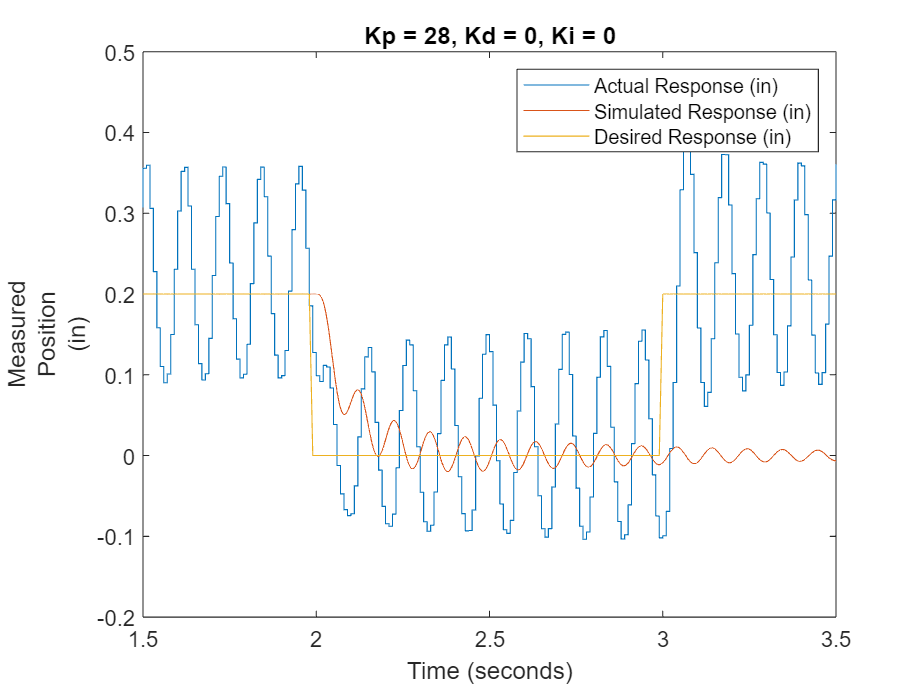


%week 1 part 4e
Kp = 28;
Kd = 0;
Ki = 0;
run4e = sim('Hydraulic_Lab_BD.slx');
data4e = load('4e-R12-3.mat');
data4e = data4e.data(1);
response = data4e{4}.Values;
fig4e = figure(); 
plot(response)
hold on
plot(run4e.tout, run4e.step)
hold on 
plot(data4e{2}.Values)
hold on 
xlim([1.5 3.5])
legend('Actual Response (in)', 'Simulated Response (in)', 'Desired Response (in)')
title('Kp = 28, Kd = 0, Ki = 0')
hold off


%root locus plots 

sys = tf([5777.05],[1,42.576,3843.97,0]);

z = [10,13,20,19,28];

r = rlocus(sys,z) 

r =  -12.8164 +56.9685i -10.2160 +57.3337i  -4.8908 +59.1546i  -5.5780 +58.8416i  -0.1691 +61.8842i
 -12.8164 -56.9685i -10.2160 -57.3337i  -4.8908 -59.1546i  -5.5780 -58.8416i  -0.1691 -61.8842i
 -16.9431 + 0.0000i -22.1439 + 0.0000i -32.7944 + 0.0000i -31.4200 + 0.0000i -42.2378 + 0.0000i


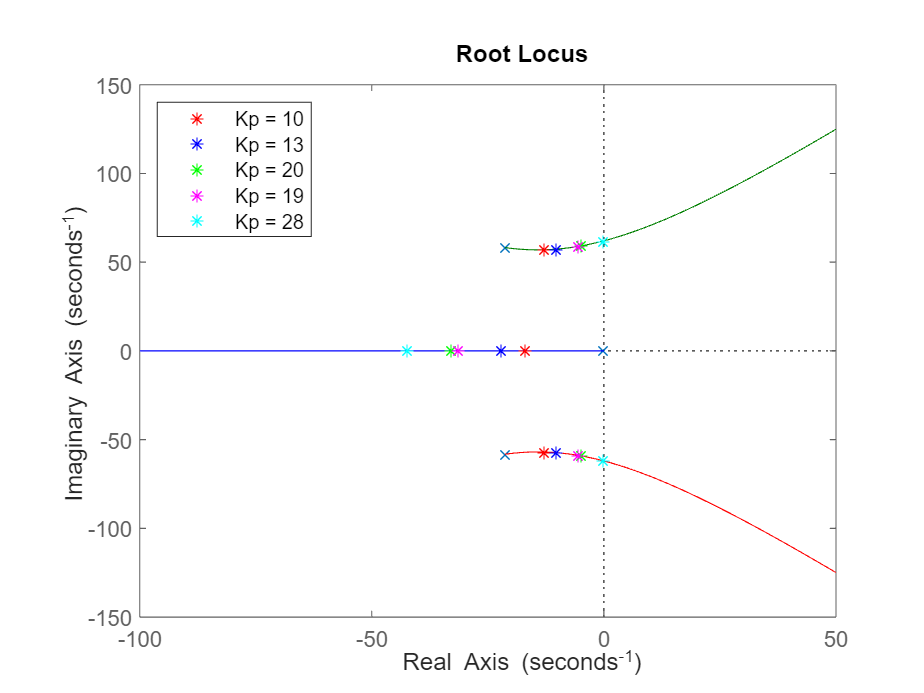

rlfig = figure();
rlocus(sys)
hold on 
plot(-12.8164,56.9685,'*','Color','r')
hold on 
plot(-12.8164,-56.9685,'*','Color','r')
hold on 
plot(-16.9431,0.0000,'*','Color','r')
hold on 
plot(-10.2160,57.3337,'*','Color','b')
hold on 
plot(-10.2160,-57.3337,'*','Color','b')
hold on 
plot(-22.1439,0.0000,'*','Color','b')
hold on 
plot(-4.8908,59.1546,'*','Color','g')
hold on 
plot(-4.8908,-59.1546,'*','Color','g')
hold on 
plot(-32.7944,0.0000,'*','Color','g')
hold on 
plot(-5.5780,58.8416,'*','Color','m')
hold on 
plot(-5.5780,-58.8416,'*','Color','m')
hold on 
plot(-31.4200,0.0000,'*','Color','m')
hold on 
plot(-0.1691,61.8842,'*','Color','c')
hold on 
plot(-0.1691,-61.8842,'*','Color','c')
hold on 
plot(-42.2378,0.0000,'*','Color','c')
legend({'','Kp = 10','','','Kp = 13','','','Kp = 20','','','Kp = 19','','','Kp = 28','',''},'Location','northwest');
axis([-100 50 -150 150])

## Week 2 

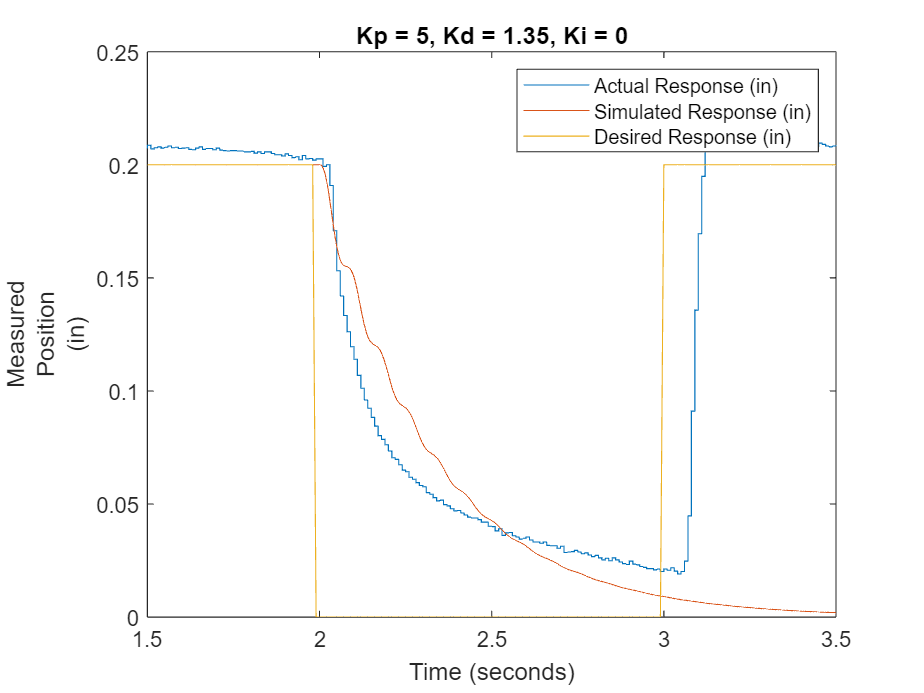

%Plotting part 2a from week 2
Kp = 12;
Kd = 1.35;
Ki = 0;
run1 = sim('Hydraulic_Lab_BD.slx');
data2a = load('P5D1.35week2a.mat');
data2a = data2a.data(1);
response = data2a{4}.Values;
fig2a = figure(); 
plot(response)
hold on
plot(run1.tout, run1.step)
hold on 
plot(data2a{2}.Values)
hold on 
xlim([1.5 3.5])
legend('Actual Response (in)', 'Simulated Response (in)', 'Desired Response (in)')
title('Kp = 5, Kd = 1.35, Ki = 0')
hold off

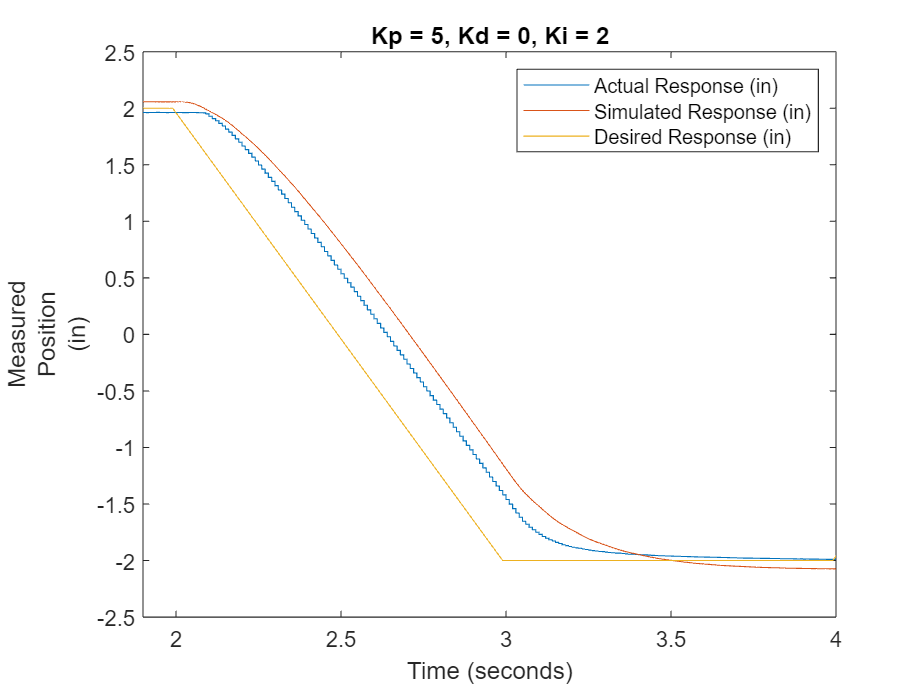



%Plotting part 2b from week 2
Kp = 12;
Kd = 0;
Ki = 2;
run1 = sim('Hydraulic_Lab_BD.slx');
data2b = load('P5I2week2b.mat');
data2b = data2b.data(1);
response = data2b{4}.Values;
fig2b = figure(); 
plot(response)
hold on
plot(run1.tout, run1.ramp)
hold on 
plot(data2b{2}.Values)
xlim([1.9 4])
legend('Actual Response (in)', 'Simulated Response (in)', 'Desired Response (in)')
title('Kp = 5, Kd = 0, Ki = 2')
hold off

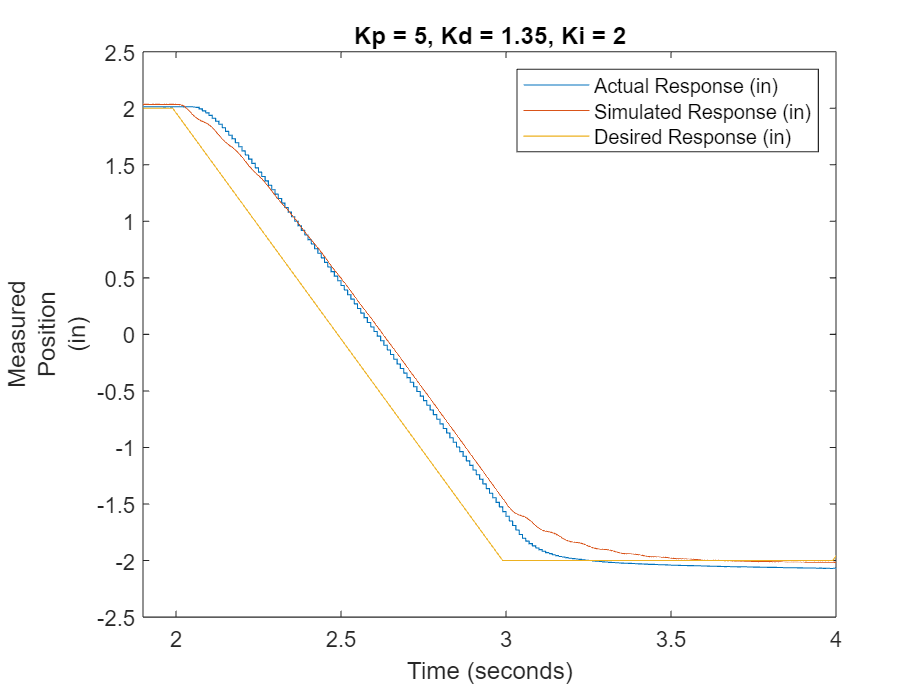

%Plotting part 2c from week 2
Kp = 20;
Kd = 1.35;
Ki = 2;
run1 = sim('Hydraulic_Lab_BD.slx');
data2c = load('P5I2D1.35week2c.mat');
data2c = data2c.data(1);
response = data2c{4}.Values;
fig2c = figure(); 
plot(response(:,1))
hold on
plot(run1.tout, run1.ramp)
hold on 
plot(data2c{2}.Values)
xlim([1.9 4])
legend('Actual Response (in)', 'Simulated Response (in)', 'Desired Response (in)')
title('Kp = 5, Kd = 1.35, Ki = 2')
hold off